%import all data from CSVs, then:
%TESTCONFUSION = table2array(TESTCONFUSION);
maxEpoch = 150;
epochNum = (1:maxEpoch)';
correct = table2array(backtestLog(:,["Correct"]));
samples = 10000;
testAcc = (correct./samples)*100;

trainingCost = table2array(trainingLog(:,["AvgCost"]));
trainingAcc = table2array(trainingLog(:,["EpochAcc"]));

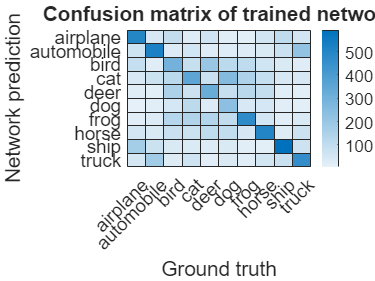

clim([100, 600]);
labels = ["airplane", "automobile", "bird", "cat", "deer",  ...
            "dog", "frog", "horse", "ship", "truck"];
heatmap(labels, labels, TESTCONFUSION);
xlabel("Ground truth");
ylabel("Network prediction");
title("Confusion matrix of trained network");
fontsize(14, "points");
fontname("Helvetica");

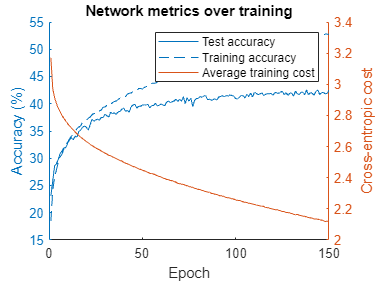

clf
hold on
title("Network metrics over training")
yyaxis("left")
plot(testAcc);
plot(trainingAcc);
xlabel("Epoch")
ylabel("Accuracy (%)")

yyaxis("right")
plot(trainingCost)
ylabel("Cross-entropic cost")
legend(["Test accuracy", "Training accuracy", "Average training cost"])